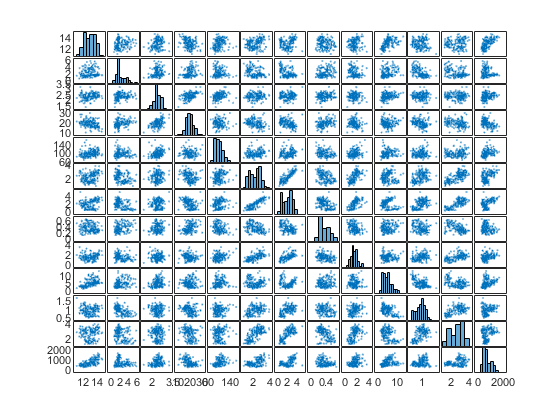

predictorNames = {'Alcohol', 'MalicAcid', 'Ash', 'AlcalinityOfAsh', 'Magnesium', 'TotalPhenols', 'Flavanoids', 'NonflavanoidPhenols', 'Proanthocyanins', 'ColorIntensity', 'Hue', 'OD280_OD315OfDilutedWines', 'Proline'};
predictors = datasetTable(:,predictorNames);    %determines dependent variables
predictors = table2array(varfun(@double, predictors));
response = datasetTable.Class;  %independent variable. E.g. Wine determined from dependent variables

X = predictors; %dependent values, magnesium etc
Y = response;   %the guess we are trying to evaluate, Which wine corresponds

S = std(X);
M = mean(X);
V = var(X);

%***Scatter Plot***
plotmatrix(X);

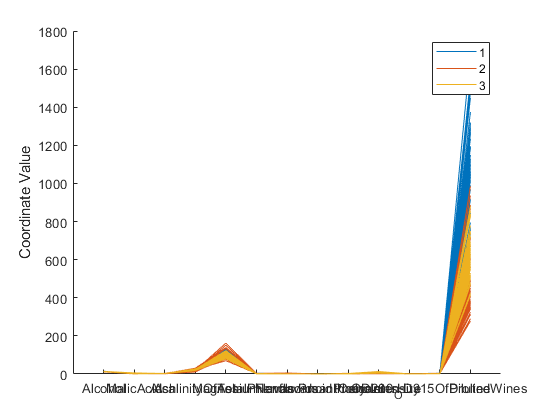


%***Parallel Coords***
%x axis in parallelcoords plot
labels = {'Alcohol', 'MalicAcid', 'Ash', 'AlcalinityOfAsh', 'Magnesium', 'TotalPhenols', 'Flavanoids', 'NonflavanoidPhenols', 'Proanthocyanins', 'ColorIntensity', 'Hue', 'OD280_OD315OfDilutedWines', 'Proline'};

%parallel coordinate plot
parallelcoords(X, 'Group', Y, 'Labels', labels);

S

S =     0.8118    1.1171    0.2743    3.3396   14.2825    0.6259    0.9989    0.1245    0.5724    2.3183    0.2286    0.7100  314.9075


M

M =    13.0006    2.3363    2.3665   19.4949   99.7416    2.2951    2.0293    0.3619    1.5909    5.0581    0.9574    2.6117  746.8933


V

V = 	1.0e+04 *

    0.0001    0.0001    0.0000    0.0011    0.0204    0.0000    0.0001    0.0000    0.0000    0.0005    0.0000    0.0001    9.9167
